# Word-by-Word Text Generation Using Deep Learning

This example shows how to train a deep learning LSTM network to generate text word-by-word.

Link: https://www.mathworks.com/help/deeplearning/ug/word-by-word-text-generation-using-deep-learning.html

To train a deep learning network for word-by-word text generation, train a sequence-to-sequence LSTM network to predict the next word in a sequence of words. To train the network to predict the next word, specify the responses to be the input sequences shifted by one time step.

This example reads text from a website. It reads and parses the HTML code to extract the relevant text, then uses a custom mini-batch datastore `documentGenerationDatastore` to input the documents to the network as mini-batches of sequence data. The datastore converts documents to sequences of numeric word indices. The deep learning network is an LSTM network that contains a word embedding layer.

A mini-batch datastore is an implementation of a datastore with support for reading data in batches. You can use a mini-batch datastore as a source of training, validation, test, and prediction data sets for deep learning applications. Use mini-batch datastores to read out-of-memory data or to perform specific preprocessing operations when reading batches of data.

You can adapt the custom mini-batch datastore specified by `documentGenerationDatastore` to your data by customizing the functions. This file is attached to this example as a supporting file. To access this file, open the example as a live script. For an example showing how to create your own custom mini-batch datastore, see [Develop Custom Mini-Batch Datastore](docid:nnet_ug#mw_0efea122-cbfb-4a68-8e77-387fd3c78e50). 

## Load Training Data

Load the training data. Read the HTML code from [Alice's Adventures in Wonderland by Lewis Carroll](https://www.gutenberg.org/files/11/11-h/11-h.htm) from Project Gutenberg.

url = "https://www.gutenberg.org/files/11/11-h/11-h.htm";
code = webread(url);

## Parse HTML Code

The HTML code contains the relevant text inside `<p>` (paragraph) elements. Extract the relevant text by parsing the HTML code using `htmlTree` and then finding all the elements with element name `"p"`.

tree = htmlTree(code);
selector = "p";
subtrees = findElement(tree,selector);

Extract the text data from the HTML subtrees using `extractHTMLText` and view the first 10 paragraphs.

textData = extractHTMLText(subtrees);
textData(1:10)

ans = 10×1 string array
    "Alice was beginning to get very tired of sitting by her sister on the bank, and of having nothing to do: once or twice she had peeped into the book her sister was reading, but it had no pictures or conversations in it, “and what is the use of a book,” thought Alice “without pictures or conversations?”"
    "So she was considering in her own mind (as well as she could, for the hot day made her feel very sleepy and stupid), whether the pleasure of making a daisy-chain would be worth the trouble of getting up and picking the daisies, when suddenly a White Rabbit with pink eyes ran close by her."
    "There was nothing so very remarkable in that; nor did Alice think it so very much out of the way to hear the Rabbit say to itself, “Oh dear! Oh dear! I shall be late!” (when she thought it over afterwards, it occurred to her that she ought to have wondered at this, but at the time it all seemed quite natural); but when the Rabbit actually took a watch out of its w

Remove the empty paragraphs and view the first 10 remaining paragraphs.

textData(textData == "") = [];
textData(1:10)

ans = 10×1 string array
    "Alice was beginning to get very tired of sitting by her sister on the bank, and of having nothing to do: once or twice she had peeped into the book her sister was reading, but it had no pictures or conversations in it, “and what is the use of a book,” thought Alice “without pictures or conversations?”"
    "So she was considering in her own mind (as well as she could, for the hot day made her feel very sleepy and stupid), whether the pleasure of making a daisy-chain would be worth the trouble of getting up and picking the daisies, when suddenly a White Rabbit with pink eyes ran close by her."
    "There was nothing so very remarkable in that; nor did Alice think it so very much out of the way to hear the Rabbit say to itself, “Oh dear! Oh dear! I shall be late!” (when she thought it over afterwards, it occurred to her that she ought to have wondered at this, but at the time it all seemed quite natural); but when the Rabbit actually took a watch out of its w

Visualize the text data in a word cloud.

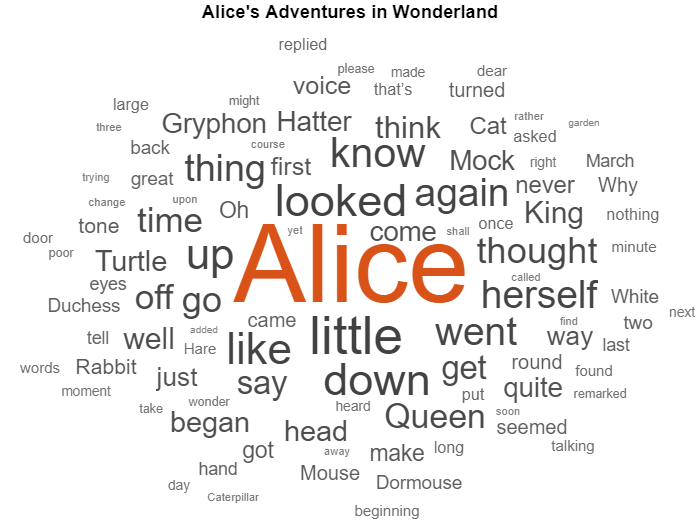

figure
wordcloud(textData);
title("Alice's Adventures in Wonderland")

## Prepare Data for Training

Create a datastore that contains the data for training using `documentGenerationDatastore`. For the predictors, this datastore converts the documents into sequences of word indices using a word encoding. The first word index for each document corresponds to a "start of text" token. The "start of text" token is given by the string `"startOfText"`. For the responses, the datastore returns categorical sequences of the words shifted by one.

Tokenize the text data using `tokenizedDocument`.

documents = tokenizedDocument(textData);

Create a document generation datastore using the tokenized documents.

ds = documentGenerationDatastore(documents);

To reduce the amount of padding added to the sequences, sort the documents in the datastore by sequence length.

ds = sort(ds);

## Create and Train LSTM Network

Define the LSTM network architecture. To input sequence data into the network, include a sequence input layer and set the input size to 1. Next, include a word embedding layer of dimension 100 and the same number of words as the word encoding. Next, include an LSTM layer and specify the hidden size to be 100. Finally, add a fully connected layer with the same size as the number of classes, a softmax layer, and a classification layer. The number of classes is the number of words in the vocabulary plus an extra class for the "end of text" class.

inputSize = 1;
embeddingDimension = 100;
numWords = numel(ds.Encoding.Vocabulary);
numClasses = numWords + 1;

layers = [ 
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(500)
    dropoutLayer(0.2)
    fullyConnectedLayer(numClasses)
    softmaxLayer];
analyzeNetwork(layers)

Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:nnet_ref#mw_11ce840f-eed7-4975-9c28-baeebd79f092) app.

- Specify the solver to be `'adam'`.

- Train for 400 epochs with learn rate 0.01.

- Set the mini-batch size to 32. 

- To keep the data sorted by sequence length, set the `'Shuffle'` option to `'never'`. 

- To monitor the training progress, set the `'Plots'` option to `'training-progress'`.

- To suppress verbose output, set `'Verbose'` to `false`.

options = trainingOptions('adam', ...
    'InputDataFormats','CTB', ...
    'MaxEpochs',400, ...
    'InitialLearnRate',0.01, ...
    'MiniBatchSize',128, ...
    'Shuffle','never', ...
    'Plots','training-progress', ...
    'Metrics', 'accuracy', ...
    'Verbose',false, ...
    'ExecutionEnvironment','gpu');

Train the neural network using the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. For classification, use cross-entropy loss. By default, the `trainnet` function uses a GPU if one is available. Training on a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the `trainnet` function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

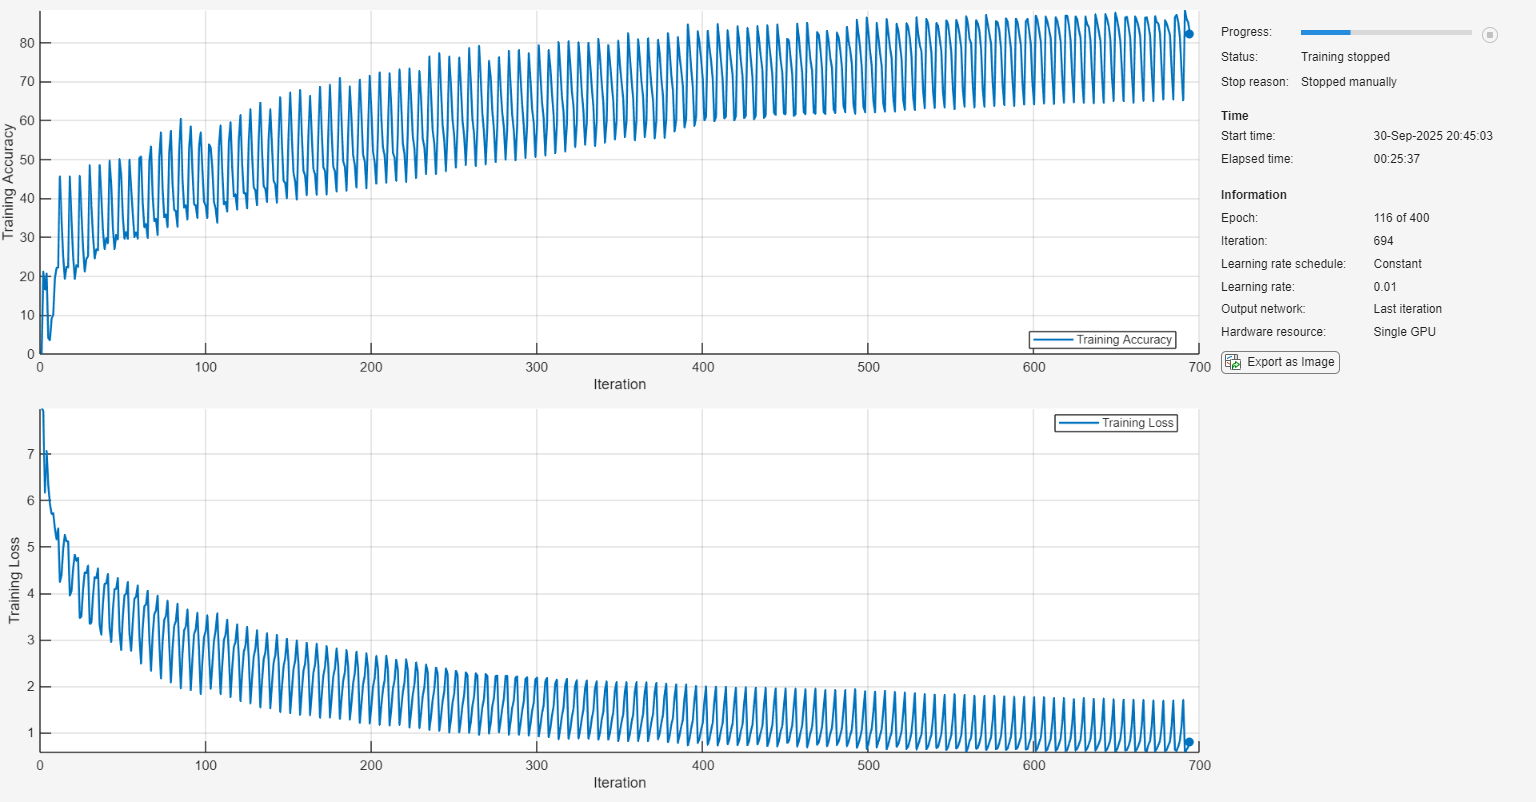

net = trainnet(ds,layers,"crossentropy",options);

## Generate New Text

Generate the first word of the text by sampling a word from a probability distribution according to the first words of the text in the training data. Generate the remaining words by using the trained LSTM network to predict the next time step using the current sequence of generated text. Keep generating words one-by-one until the network predicts the "end of text" word.

To make the first prediction using the network, input the index that represents the "start of text" token. Find the index by using the `word2ind` function with the word encoding used by the document datastore.

enc = ds.Encoding;
wordIndex = word2ind(enc,"startOfText")

wordIndex = 1

For the remaining predictions, sample the next word according to the prediction scores of the network. The prediction scores represent the probability distribution of the next word. Obtain the vocabulary from the `wordEncoding` `Vocabulary` property and include the "EndOfText" token, which is added at the end of each observation.

vocabulary = [enc.Vocabulary "EndOfText"];

Make predictions word by word using the `predict` function. For each prediction, input the index of the previous word. Stop predicting when the network predicts the end of text word or when the generated text is 500 characters long. For large collections of data, long sequences, or large networks, predictions on the GPU are usually faster to compute than predictions on the CPU. Otherwise, predictions on the CPU are usually faster to compute. To use a GPU, first convert the data to `gpuArray`.

generatedText = "";
maxLength = 500;
while strlength(generatedText) < maxLength
    % Predict the next word scores.
    [wordScores,state] = predict(net,wordIndex);
    net.State = state;
    
    % Sample the next word.
    newWord = datasample(vocabulary,1,'Weights',wordScores);
    
    % Stop predicting at the end of text.
    if newWord == "EndOfText"
        break
    end
    
    % Add the word to the generated text.
    generatedText = generatedText + " " + newWord;
    
    % Find the word index for the next input.
    wordIndex = word2ind(enc,newWord);
end

Error using datasample (line 123)
Value of Weights must not be a gpuArray.

The generation process introduces whitespace characters between each prediction, which means that some punctuation characters appear with unnecessary spaces before and after. Reconstruct the generated text by removing the spaces before and after the appropriate punctuation characters.

Remove the spaces that appear before the specified punctuation characters.

punctuationCharacters = ["." "," "’" ")" ":" "?" "!"];
generatedText = replace(generatedText," " + punctuationCharacters,punctuationCharacters);

Remove the spaces that appear after the specified punctuation characters.

punctuationCharacters = ["(" "‘"];
generatedText = replace(generatedText,punctuationCharacters + " ",punctuationCharacters)

To generate multiple pieces of text, reset the network state between generations using `resetState`.

net = resetState(net);

*Copyright 2018-2023 The MathWorks, Inc.*